clc; clear;
syms l1 l2 l3 d1 d2 d3 theta1 theta2 theta3

DH =    [l1 d1 0 0;
        l2 0 0 theta2;
        l3 0 0 theta3];
q = [0, pi/4, pi/4];
l = [1245 685 685];

bot1 = manipulator(DH,l);
T = bot1.fkine()

$$T = \left(\begin{array}{cccc} \cos\left(\theta_{2}+\theta_{3}\right) & -\sin\left(\theta_{2}+\theta_{3}\right) & 0 & 685\,\cos\left(\theta_{2}+\theta_{3}\right)+685\,\cos\left(\theta_{2}\right)+1245\\ \sin\left(\theta_{2}+\theta_{3}\right) & \cos\left(\theta_{2}+\theta_{3}\right) & 0 & 685\,\sin\left(\theta_{2}+\theta_{3}\right)+685\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%T = bot1.fkine(q)

%J = bot1.Jacobian() %Validate this result
%bot1.currentProperties


%Identify joint limits
%Joint 2 - -90 -> 90
%Need to define plane that end effector can't go through (theta3)
%This will be a function of link lengths 
%This would mean we don't need constraint for joint 2 if we keep checking
%this
%Checking the final transformation matrix

%Need to check each result to ensure it doesn't include a joint values
%outside of these limits


[a, b, c] = bot1.ikine([10 10 20])

a = 20

b =     1.9005    2.7957


c =     0.6756    2.4660


%T1 = bot1.fkine([d1 theta2 theta3])
T_test = eval(bot1.fkine([a, b(1,1), c(1,1)]))

T_test = 1.0e+03 *

   -0.0008   -0.0005         0    0.4449
    0.0005   -0.0008         0    1.0151
         0         0    0.0010    0.0200
         0         0         0    0.0010


%T_test = eval(bot1.fkine([a, b(1,1), c(1,1)]))
Tk_plus = simplify(subs(T,{d1,theta2,theta3}, {a,b(1,1),c(1,1)}));%The plus of theta3
%Tk_minus = simplify(subs(T,{d1,theta2,theta3}, {a,b(1,2),c(1,2)}));%The minus of theta3
Tk_plus = eval(Tk_plus)

Tk_plus = 1.0e+03 *

   -0.0008   -0.0005         0    0.4449
    0.0005   -0.0008         0    1.0151
         0         0    0.0010    0.0200
         0         0         0    0.0010


%Tk_minus = eval(Tk_minus)

Tk_minus =     0.5221    0.8529         0  958.2022
   -0.8529    0.5221         0 -351.9873
         0         0    1.0000   20.0000
         0         0         0    1.0000





%{
y = T(2,4);
x = T(1,4);
D = (y^2 + (x-l(1,1))^2 - l(1,2)^2 - l(1,3)^2)/(2*l(1,2)*l(1,3))

$$D = \frac{{\left(685\,\cos\left(\theta_{2}+\theta_{3}\right)+685\,\cos\left(\theta_{2}\right)\right)}^{2}}{938450}+\frac{{\left(685\,\sin\left(\theta_{2}+\theta_{3}\right)+685\,\sin\left(\theta_{2}\right)\right)}^{2}}{938450}-1$$

theta3_plus = simplify(atan2(D,sqrt(1-D^2)))

$$theta3\_plus = \text{atan2}\left(\cos\left(\theta_{3}\right),\sqrt{1-{\cos\left(\theta_{3}\right)}^{2}}\right)$$

theta3_minus = simplify(atan2(D,-sqrt(1-D^2)))

$$theta3\_minus = \text{atan2}\left(\cos\left(\theta_{3}\right),-\sqrt{1-{\cos\left(\theta_{3}\right)}^{2}}\right)$$

theta2_minus = simplify(atan2(y,x-l(1,1)) - atan2(l(1,2) + l(1,3)*cos(theta3_minus),l(1,3)*sin(theta3_minus)))

$$theta2\_minus = -\text{angle}\left(-\frac{\left(\mathrm{imag}\left(\cos\left(\theta_{3}\right)\right)-\left|\sqrt{1-{\cos\left(\theta_{3}\right)}^{2}}-\cos\left(\theta_{3}\right)\,\mathrm{i}\right|+\mathrm{real}\left(\sqrt{1-{\cos\left(\theta_{3}\right)}^{2}}\right)+\mathrm{real}\left(\cos\left(\theta_{3}\right)\right)\,\mathrm{i}-\mathrm{imag}\left(\sqrt{1-{\cos\left(\theta_{3}\right)}^{2}}\right)\,\mathrm{i}\right)\,\mathrm{i}}{\left|\sqrt{1-{\cos\left(\theta_{3}\right)}^{2}}-\cos\left(\theta_{3}\right)\,\mathrm{i}\right|}\right)+\text{atan2}\left(685\,\sin\left(\theta_{2}+\theta_{3}\right)+685\,\sin\left(\theta_{2}\right),685\,\cos\left(\theta_{2}+\theta_{3}\right)+685\,\cos\left(\theta_{2}\right)\right)$$

theta2_plus = simplify(atan2(y,x-l(1,1)) - atan2(l(1,2) + l(1,3)*cos(theta3_plus),l(1,3)*sin(theta3_plus)))

$$theta2\_plus = \text{atan2}\left(685\,\sin\left(\theta_{2}+\theta_{3}\right)+685\,\sin\left(\theta_{2}\right),685\,\cos\left(\theta_{2}+\theta_{3}\right)+685\,\cos\left(\theta_{2}\right)\right)-\text{angle}\left(-\frac{\left(\mathrm{imag}\left(\cos\left(\theta_{3}\right)\right)-\left|\sqrt{1-{\cos\left(\theta_{3}\right)}^{2}}+\cos\left(\theta_{3}\right)\,\mathrm{i}\right|-\mathrm{real}\left(\sqrt{1-{\cos\left(\theta_{3}\right)}^{2}}\right)+\mathrm{real}\left(\cos\left(\theta_{3}\right)\right)\,\mathrm{i}+\mathrm{imag}\left(\sqrt{1-{\cos\left(\theta_{3}\right)}^{2}}\right)\,\mathrm{i}\right)\,\mathrm{i}}{\left|\sqrt{1-{\cos\left(\theta_{3}\right)}^{2}}+\cos\left(\theta_{3}\right)\,\mathrm{i}\right|}\right)$$


%}

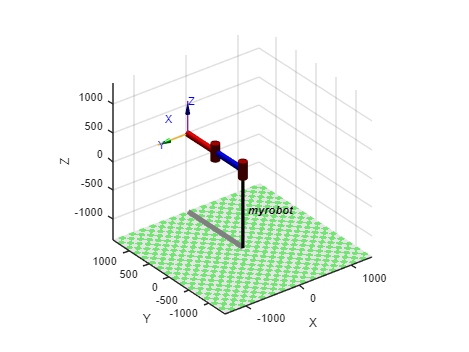


%Using robotics toolbox to confirm results
%L1 = Link('a', l(1,1), 'alpha', pi/2, 'theta', 0, 'qlim',[0 40]);
%L1 = Link('a', l(1,1),'d',0, 'alpha', 0);
L2 = Link('a', 685,'d',0, 'alpha', 0);
L3 = Link('a', 685,'d',0, 'alpha', 0);

bot = SerialLink([L2 L3], 'name', 'myrobot');
%T1 = bot.fkine(q)
%bot.base = trotz(pi/2);
bot.plot([pi/2 0])